# limitations of sparsity w.r.t. a basis

close all
clear
clc

clc
N = 32; % signal dimension
M = 32; % nr of atoms in the span (for basis M = N)

C = nan(N, M); % matrix containing the standard basis (a kronecker delta in each column)
D = nan(N, M); % matrix containing the DCT basis (a DCT function in each column)

## generate the 1D-DCT basis

disp('generating 1-D DCT basis')

generating 1-D DCT basis


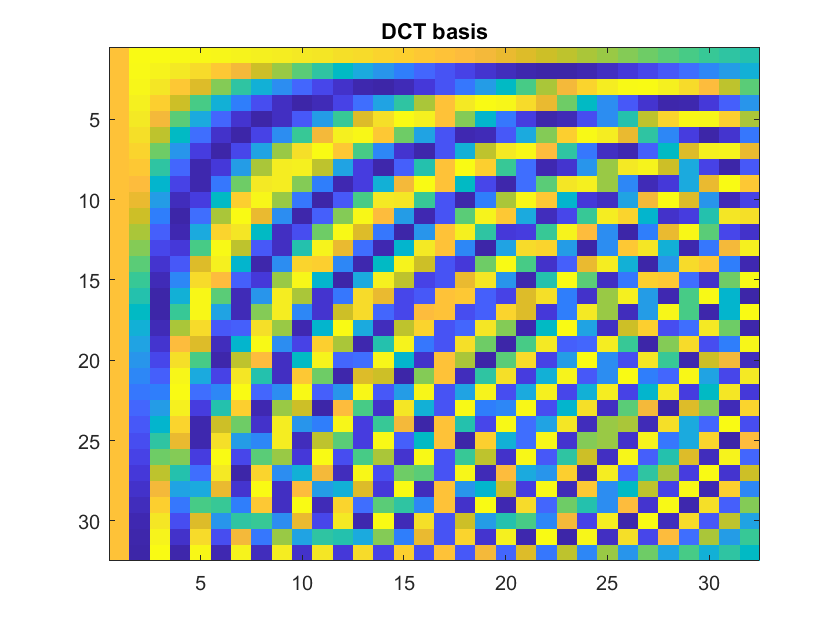

for j=1:1:M
    a = zeros(N,1);
    a(j) = 1;
    D(:,j) = idct(a);
end
figure(3), imagesc(D), title('DCT basis');

## Generate a signal that is sparse w.r.t. D

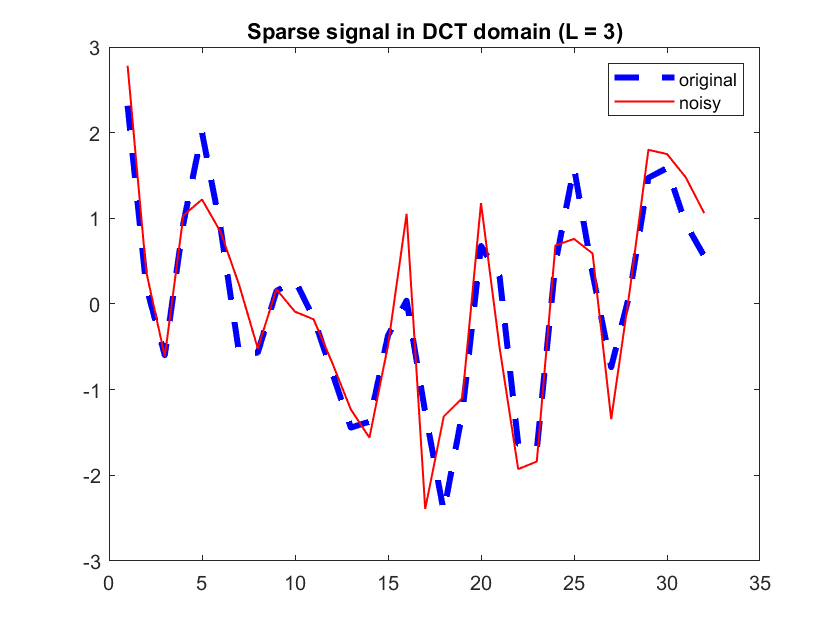

L = 3; % signal sparsity
sigma_noise = 0.5; %noise to be added to the signal

% randomly define the coefficients of a sparse representation (make sure the nonzero coefficients are sufficiently large)
values = 1./exprnd(0.2, 1, L);
indexes = randsample(N, L);
x0 = zeros(N, 1);
x0(indexes) = values;

% synthetize the corresponding signal in the signal domain
s0 = D * x0;

% add noise to the signal
s = s0 + random('normal', 0, sigma_noise, size(s0));

% plot the sparse signal TODO: try using different values of L
LN_WDT = 2;
MRK_SZ = 10;

figure(4)
plot(s0, 'b--',  'LineWidth', LN_WDT + 1),
hold on
plot(s, 'r-',  'LineWidth', LN_WDT -1),
title(['Sparse signal in DCT domain (L = ', num2str(L), ')']);
hold off
legend('original', 'noisy')

## Implement the sparsity-promoting denoising. This is expected to be very effective on S!

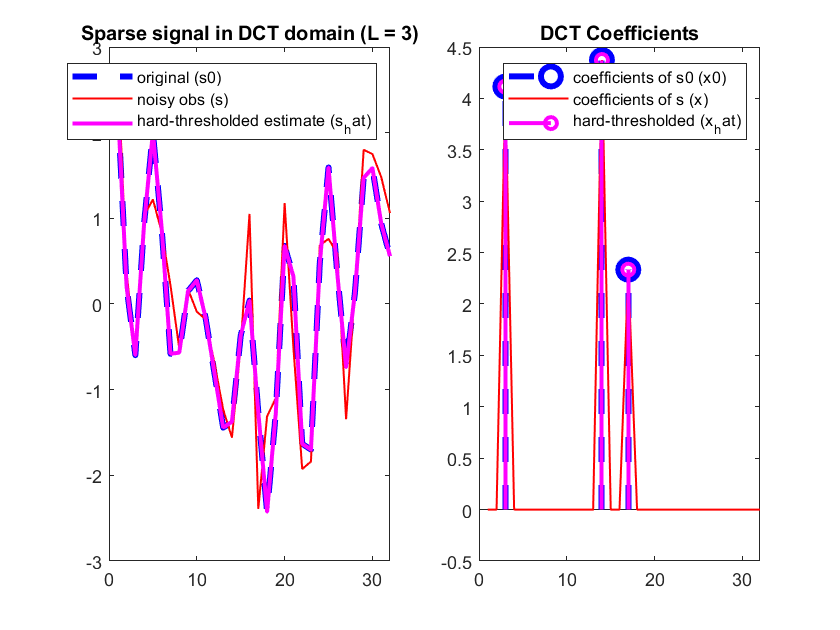

% analysis: compute the coefficients w.r.t. D 
x = D \ s0;

% keep only the L largest coefficients (absolute value) and remember not to modify the DC coefficient 
[~, argidx] = maxk(abs(x), L);
x_hat = zeros(N,1);
x_hat(argidx) = x(argidx);

% invert the transformation
s_hat = D * x_hat;

% Show the results
figure(5)
subplot(1,2,1)
plot(s0, 'b--',  'LineWidth', LN_WDT + 1),
hold on
plot(s, 'r-',  'LineWidth', LN_WDT -1),
plot(s_hat, 'm-', 'LineWidth', LN_WDT),
title(['Sparse signal in DCT domain (L = ', num2str(L), ')']);
hold off
legend('original (s0)', 'noisy obs (s)', 'hard-thresholded estimate (s_hat)')

subplot(1,2,2)
stem(find(x0 ~= 0), x0(x0~= 0), 'b--',  'LineWidth', LN_WDT + 1, 'MarkerSize', MRK_SZ),
hold on
plot(x, 'r-',  'LineWidth', LN_WDT -1),
stem(find(x_hat ~= 0), x_hat(x_hat ~= 0), 'm-', 'LineWidth', LN_WDT),
title('DCT Coefficients')
hold off
legend('coefficients of s0 (x0)', 'coefficients of s (x)', 'hard-thresholded (x_hat)')

## generate Standard orthonormal basis

disp('generating 1-D standard basis')

generating 1-D standard basis


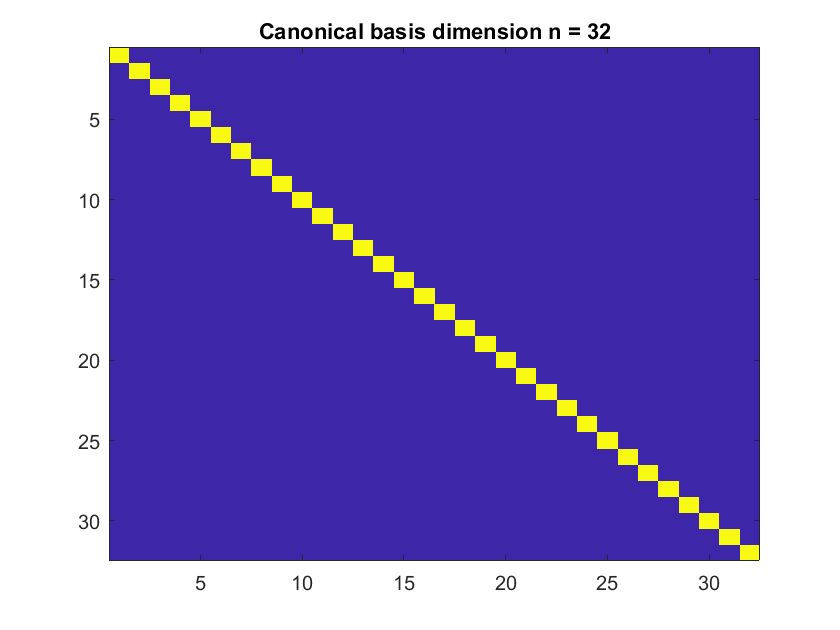

cnt = 1;
for ii = 1 : M
    a = zeros(1, M);
    a(ii) = 1;
    C(:, cnt) = a;
    cnt = cnt + 1;
end
figure(2), imagesc(C), title(['Canonical basis dimension n = ', num2str(M)]);

## generate signals that are sparse w.r.t. [C, D], i.e. add a spike to the sum of few DCT atoms

add a spike to s that is sparse w.r.t. D, bear in mind that the spike is to be considered a signal to be reconstructed, rather than noise    

## generate a signal that is sparse w.r.t. D

## randomly place a spike in the first 20 samples of s

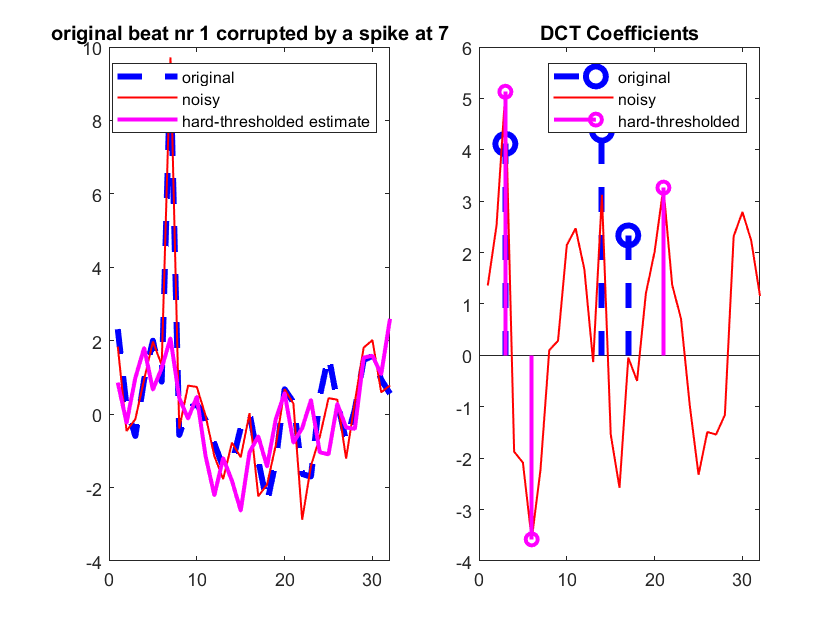

% perform this in a for loop 
nSignals = 1;
s0 = D * x0;

for ii = 1 : nSignals    
    % choose spike location
    spikeLocation = randsample(20, 1);
    a = zeros(N, 1);
    a(spikeLocation) = 10;
    % modify the signal intensity at spikeLocation
    s0 = s0 + a;
    %Add noise and perform hard thresholding
    s = s0 + random('normal', 0, sigma_noise, size(s0));
    
    x = D \ s;
    [~, argidx] = maxk(abs(x), L);
    x_hat = zeros(N,1);
    x_hat(argidx) = x(argidx);

    % invert the transformation
    s_hat = D * x_hat;
    figure(5)
    subplot(1,2,1)
    plot(s0, 'b--',  'LineWidth', LN_WDT + 1),
    hold on
    plot(s, 'r-',  'LineWidth', LN_WDT -1),
    
    plot(s_hat, 'm-', 'LineWidth', LN_WDT),
    title(['original beat nr ', num2str(ii), ' corrupted by a spike at ', num2str(spikeLocation)]);
    hold off
    legend('original', 'noisy', 'hard-thresholded estimate')
    
    subplot(1,2,2)
    stem(find(x0 ~= 0), x0(x0~= 0), 'b--',  'LineWidth', LN_WDT + 1, 'MarkerSize', MRK_SZ),
    hold on
    plot(x, 'r-',  'LineWidth', LN_WDT -1),
    stem(find(x_hat ~= 0), x_hat(x_hat ~= 0), 'm-', 'LineWidth', LN_WDT),
    title('DCT Coefficients')
    hold off
    legend('original', 'noisy', 'hard-thresholded')
    
end